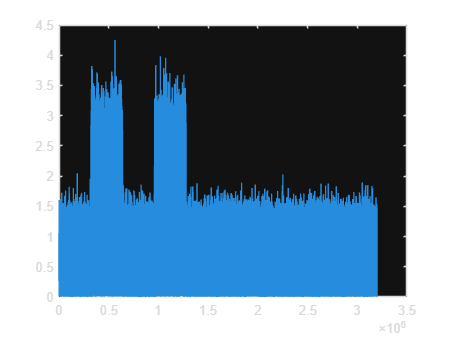

clear all;
clc;

s.N = 1024;
s.Fs = 240e6;
s.Ng = 32;
s.Midx = 4;
s.type = "QAM";
s.SNRdB = 5.5;
s.Fsr = s.Fs;

s.Nsym = 300;
s.Nsfd = 300;

s.beta = 0;
s.Fc = getClosestFch(11.775e9);
s.Fcr = s.Fc;
% s.Tdur = 1/750;
s.Tdur = 1/75;

s.tau = 0;
s.gutter = 1;
if(s.gutter == 1)
    Nd = s.N - 4;
else
    Nd = s.N;
end

x = randi([0 s.Midx-1],Nd,s.Nsym);
s.data = x;


N = 1024;
Ng = 32;
Fs = 2.4e8;

present = [0 , 1 , 0 , 1];
s.present = present;
input = genStrlkStream(s);
t = 1:length(input);
plot(t , abs(input));

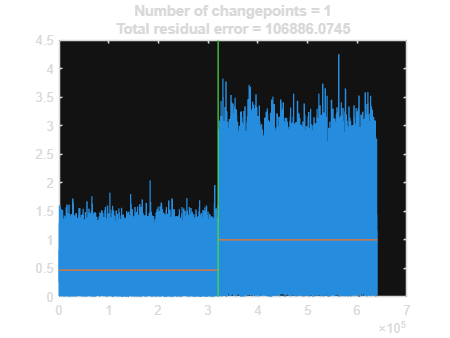

maxVal = 5.8324e-05

maxIdx = 3037

nm00 = 320000

betaidx = 1

betam = 0



s.Tf = 1/750;

[Nsf , Nsfd , Tfg] = Nsf_Nsfd_Tfg_Est(s);

